# Team doubleE - Task 2, Option 1 Report

**Team Members: Andrew Wunderlich, Jay Desai, Miles Leonard-Albert **

***CSCE585 - Machine Learning Systems***

***Fall 2020 Adversarial ML Project***

This report provides insight and analysis into Task 2, in which we create adversarial examples using the Athena framework and test the adversarial examples against several defenses to compare performance.  This report was created in MATLAB as a live script (.mlx file) and exported to a PDF.

clear variables %reset workspace
close all; %close plots from previous runs
% projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

## Import Project Data and Analyze Composition

All data from the Task 2 assignment was dumped into a single file [\data\dataTable.mat] which contains a single matrix of digits.  Each row corresponds to a single sample (image) from the test dataset. The leftmost column contains the correct labels, and the following columns contain the predictions made by Athena for each of the tested whitebox attacks. 

### Load labels and raw prediction data

%load Task 1 data to get predictions of the undefended model on benign
%samples.  Needed for determining real error rates.
load('..\Task 1\results\predictionData.mat') 
clear predictions labels %clear other unneeded variables from Task 1


load('data\dataTable.mat') %load task 2 data
labels = dataTable(:,1);
predictions = dataTable(:,2:end);
pred_bs_um = pred_bs_um(1:length(labels))';


num_images = size(predictions,1);   % rows
num_attacks = size(predictions,2);  % columns

if(length(labels) ~= num_images) 
    error('Number of labels not equal to number of images. Please check dimensions.')
end

### Analyze Composition by Labels

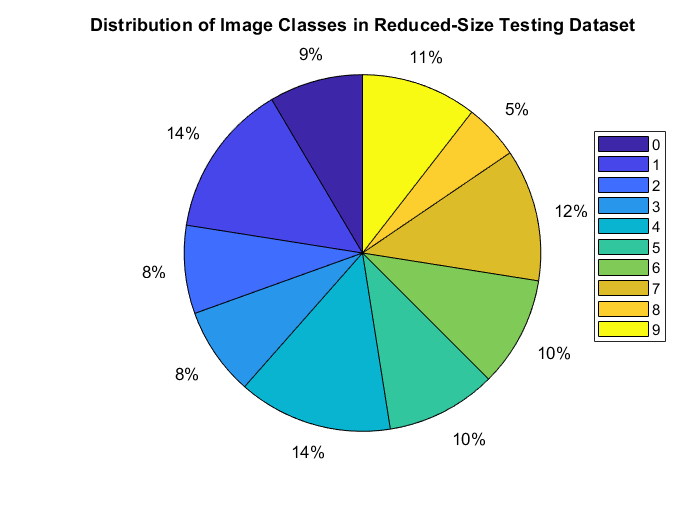

digits = unique(labels);
digitCounts = zeros(size(digits));
for i = 1:length(labels)
    for j = 1:length(digits)
        if(labels(i) == digits(j))
            digitCounts(j) = digitCounts(j) + 1;
            break;
        end
    end
end
pie(digitCounts);  title('Distribution of Image Classes in Reduced-Size Testing Dataset');
legend(string(digits), 'Position', [0.85 0.45 0.1 0.2]);

## Details About Attacks

This task includes 10 attacks, featuring the two supported whitebox attacks--FGSM and PGD--each at 5 different intensities.  Below we plot a few examples of images from the MNIST dataset modified using the following attacks:

### FGSM

with espilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

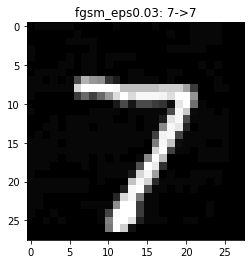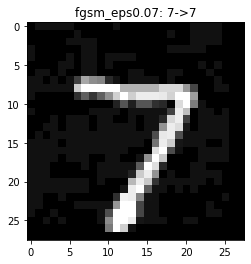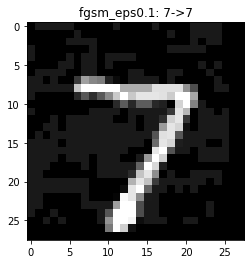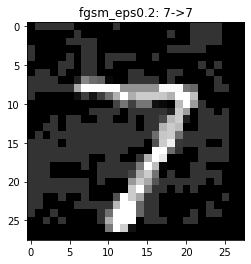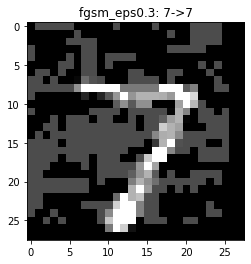

More information about the FGSM attack is available at [https://arxiv.org/abs/1412.6572](https://arxiv.org/abs/1412.6572).

### PGD

with epsilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

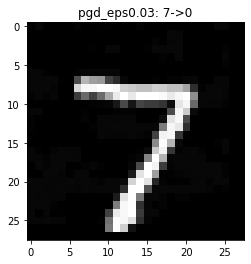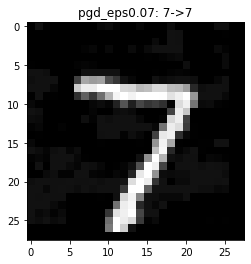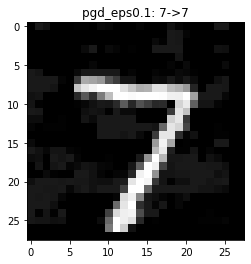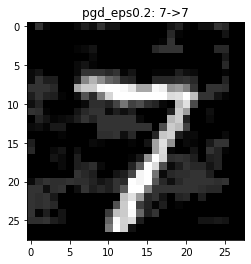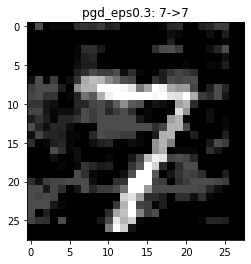

More information about the PGD attack is available at [https://arxiv.org/pdf/1706.06083.pdf](https://arxiv.org/pdf/1706.06083.pdf).

## Details about the Defense

Since whitebox attacks are crafted specifically according to the chosen defense, we only considered the Athena defense in this work.

- UM: The undefended model (a single CNN with no special defenses)

- AVEP-3: "Vanilla Athena" with the Average Probability ensemble strategy, using 3 weak defenses

- MV-3: "Vanilla Athena" with the Majority Voting ensemble strategy, using 3 weak defenses

- PGD-ADT: PGD Adversarial Training, a state-of-the-art Adversarial Defense

- AVEP-20: "Vanilla Athena" with the Average Probability ensemble strategy, using 20 weak defenses

- MV-20: "Vanilla Athena" with the Majority Voting ensemble strategy, using 20 weak defenses

In the ensemble methods, the weak defenses were chosen somewhat arbitrarily, but we made sure to choose a diverse set of weak defenses, especially in the case of the 20-WD ensembles.

## Analyzing Error Rates

We generated 2000 perturbed images (10 attack variants * 200 of the 10,000 test images in MNIST) and obtained predictions for each.  We stored the 200 correct values (labels) and stored the 2000 predicted values for each adversarial example vs the Athena defense in an array, from which we can calculate error rates and plot relevant variables.

### Calculate Error Rates

errortable = -ones(size(predictions));
all_err_rates = -ones(1,num_attacks);

for i = 1:num_attacks
    %To be error, the prediction must not match the label, and the
    %label must have been correctly identified but the undefended model
    %before the attack (i.e. against the benign samples)
    errortable(:,i) = ((predictions(:,i) ~= labels) & (labels == pred_bs_um)); 
    
    %The error rate is simply the average of error values across the row
    all_err_rates(i) = mean(errortable(:,i));
end

### Plot Error Rates by Attack

attacks = {'FGSM 0.03' 'FGSM 0.07' 'FGSM 0.10' 'FGSM 0.20' 'FGSM 0.30'...
            'PGD 0.03' 'PGD 0.07' 'PGD 0.10' 'PGD 0.20' 'PGD 0.30'};        

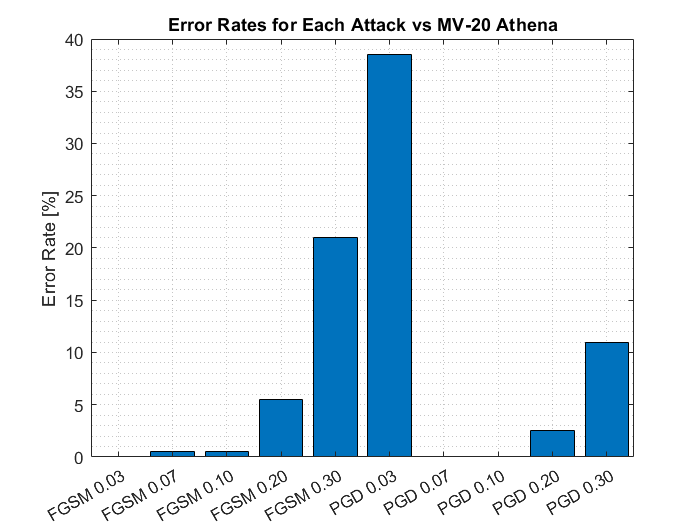

bar(categorical(attacks), all_err_rates(:)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs MV-20 Athena');

## Team Member Contributions